# Classify Disease Status with Multiplexed Reporters

patient = readtable('crispr_urineID_m.xlsx','ReadRowNames',true);
patients = patient{:,:}; % read as array
Tstart = 1; % row # first tumor sample
Tend = 12; % row # last tumor sample
Hstart = 13; % row # first healthy sample
Hend = 20; % row # last healthy sample
total_patients = 20;
plexity = 4; % number of barcodes
status = patients(:,1); % 0 indicates healthy, 1 indicates malignancy
barcode = patients(:,2:plexity+1);

% compute the regression coefficients for a linear model
X = [ones(total_patients,1) barcode];
b = regress(status,X);
% calculate the model-predicted probability of malignancy
YFIT = b(1);
for i = 1:4
    YFIT = YFIT + b(i+1).*barcode(:,i);
end    

tumor_output = YFIT(Tstart:Tend,1);
healthy_output = YFIT(Hstart:Hend,1);
[Xcoor(:,1),Ycoor(:,1),Threshold(:,1),AUC(:,1)] = perfcurve(status(:,:),YFIT,1);
for i = 1:4
    [Xcoor(:,i+1),Ycoor(:,i+1),Threshold(:,i+1),AUC(:,i+1)] = perfcurve(status(:,:),barcode(:,i),1);
end
sensor = ["4-plex";"YS3";"YS4";"YS5";"YS6"];
AUC = AUC';
table(sensor,AUC)

ans = 5x2 table
     sensor       AUC  
    ________    _______

    "4-plex"    0.92708
    "YS3"         0.875
    "YS4"       0.85417
    "YS5"       0.88542
    "YS6"       0.82292


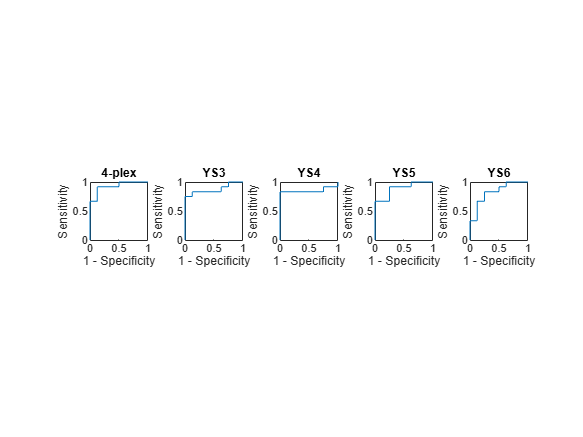

for i = 1:plexity+1
    subplot(1,plexity+1,i)
    plot(Xcoor(:,i),Ycoor(:,i))
    axis square
    xlabel('1 - Specificity') 
    ylabel('Sensitivity')
    title(sensor(i))
end